## 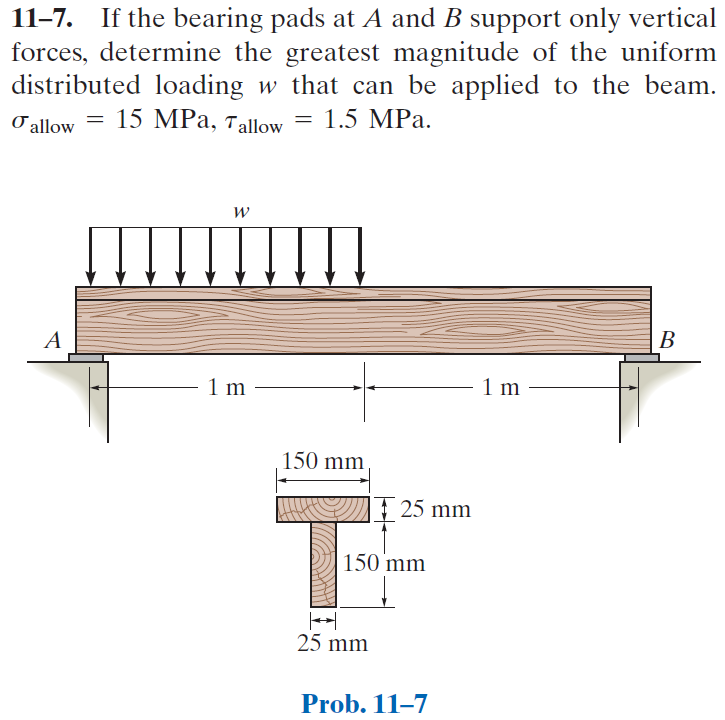

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-7P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-7P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
wo = sym('wo', 'positive');
wo_max = default_struct('bending', 'shear', 'limit');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 2*u.m);
b = b.add('distributed', 'force', -wo, [0 1]*u.m);
b.L = 2*u.m;

# section properties

yc = [150/2; 150+25/2]*u.mm;
Ac = [25*150; 150*25]*u.mm^2;
Ic = [25*150^3; 150*25^3]*u.mm^4/12;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{640000\,\mathrm{wo}\,x\,\left(2\,x^{3}-6\,x^{2}\,m+9\,m^{3}\right)}{663\,\text{E}}\,\frac{1}{m^{4}} & \text{ if }x\leq m\\ -\frac{640000\,\mathrm{wo}\,\left(x-2\,m\right)\,\left(2\,x^{2}-8\,x\,m+m^{2}\right)}{663\,\text{E}}\,\frac{1}{m^{3}} & \text{ if }m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{640000\,\mathrm{wo}\,\left(8\,x^{3}-18\,x^{2}\,m+9\,m^{3}\right)}{663\,\text{E}}\,\frac{1}{m^{4}} & \text{ if }x\leq m\\ -\frac{640000\,\mathrm{wo}\,\left(6\,x^{2}-24\,x\,m+17\,m^{2}\right)}{663\,\text{E}}\,\frac{1}{m^{3}} & \text{ if }m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x\,\left(2\,x-3\,m\right)}{4} & \text{ if }x\leq m\\ -\frac{\mathrm{wo}\,\left(x-2\,m\right)}{4}\,m & \text{ if }m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,\left(4\,x-3\,m\right)}{4} & \text{ if }x\leq m\\ -\frac{\mathrm{wo}}{4}\,m & \text{ if }m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\mathrm{wo} & \text{ if }x\leq m\\ 0 & \text{ if }m<x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & \frac{3\,\mathrm{wo}}{4}\,m\\ \mathrm{Rb} & \frac{\mathrm{wo}}{4}\,m \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

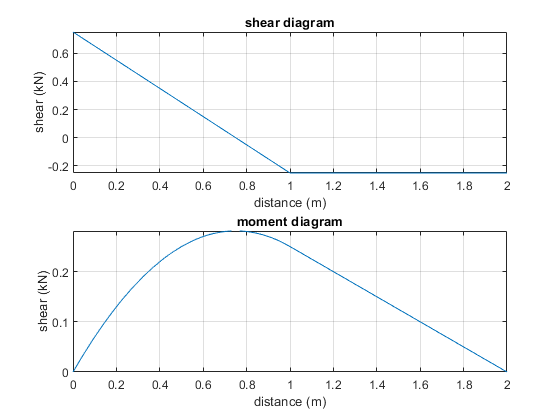

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'}, wo, 1);

# maximum loads

assume(0 < x & x < b.L);
xmax = solve(v == 0);
M_max(wo) = m(xmax)

$$M\_max(wo) = \frac{9\,\mathrm{wo}}{32}\,m^{2}$$

V_max(wo) = v(0)

$$V\_max(wo) = \frac{3\,\mathrm{wo}}{4}\,m$$

# maximum stresses

C = symmax([yn (150+25)*u.mm-yn]);
b.I = rewrite(b.I, u.mm);
sigma_max = rewrite(M_max*C/b.I, u.m)

$$sigma\_max(wo) = \frac{342000\,\mathrm{wo}}{221}\,\frac{1}{m}$$

Q_max = (yn/2)*(25*u.mm*yn);
t_min = 25*u.mm;
tau_max = rewrite(V_max*Q_max/(b.I*t_min), u.m)

$$tau\_max(wo) = \frac{54150\,\mathrm{wo}}{221}\,\frac{1}{m}$$

# maximum distributed force

sigma_allow = 15*u.MPa;
tau_allow = 1.5*u.MPa;
wo_max.bending = solve(sigma_max == rewrite(sigma_allow, [u.kN u.m]));
wo_max.bending = simplify(wo_max.bending);
wo_max_bending = vpa(wo_max.bending, 3) %#ok<NASGU> 

$$wo\_max\_bending = 9.69\,\frac{\mathrm{kN}}{m}$$

wo_max.shear = solve(tau_max == rewrite(tau_allow, [u.kN u.m]));
wo_max.shear = simplify(wo_max.shear);
wo_max_shear = vpa(wo_max.shear, 3) %#ok<NASGU> 

$$wo\_max\_shear = 6.12\,\frac{\mathrm{kN}}{m}$$

wo_max_vals = [wo_max.bending wo_max.shear];
loc = sigma_max(wo_max_vals) <= sigma_allow & ...
      tau_max(wo_max_vals) <= tau_allow;
wo_max.limit = wo_max_vals(isAlways(loc));
wo_max_limit = vpa(wo_max.limit, 3) %#ok<NASGU> 

$$wo\_max\_limit = 6.12\,\frac{\mathrm{kN}}{m}$$

# clean up

setassum(old_assum, 'clear');
clear old_assum;
clear wo_max_bending wo_max_shear wo_max_vals loc wo_max_limit;